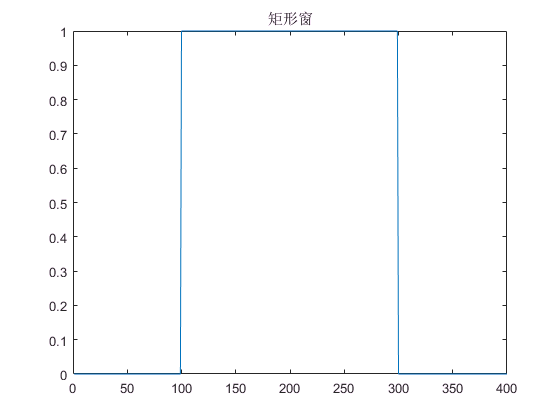

a=zeros(1, 400);
a(100:299) = ones(1, 200);
b = fft(a);
b = circshift(b', 200)';
plot(a);
title("矩形窗")

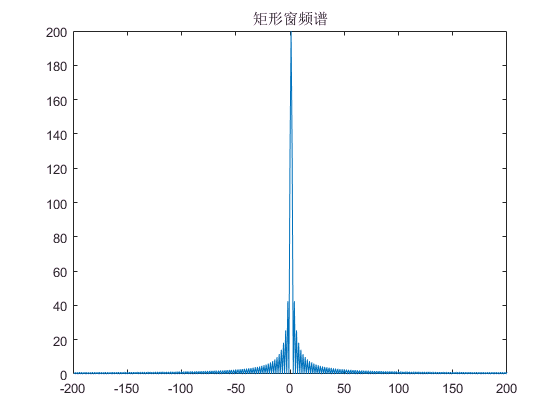


plot([-199:1:200], abs(b));
title("矩形窗频谱")


a=zeros(1, 400);
a(100:299) = hanning(200)';

在赋值 A(:) = B 中，A 和 B 中的元素数目必须相同。


plot(a);
title("汉宁窗")
b = fft(a);
b = circshift(b', 200)';

plot([-199:1:200],abs(b));
title("汉宁窗频谱")

T = 200;

x = [0:1:T-1];
sinWave = sin(2 * pi / T * 20 * x);
plot(x, sinWave);
title("频率为20的正弦波");
b = fft(sinWave);
plot(x, abs(b));
title("整数个周期正弦波的频谱")

x = [0:1:195];
sinWave = sin(2 * pi / T * 20 * x);
plot(x, sinWave);
title("19.5个周期的正弦波");
b = fft(sinWave);
%b = circshift(b', fix(length(sinWave) / 2))';
plot(x, abs(b));
title("非整数个周期正弦波的频谱")

x = [0:1:195];
window = hanning(length(x))';
plot(window);
title("汉宁窗");
sinWave = sin(2 * pi / T * 20 * x) .* window;
plot(x, sinWave);
title("加窗后的19.5个周期的正弦波");
b = fft(sinWave);
%b = circshift(b', fix(length(sinWave) / 2))';
plot(x, abs(b));
title("加窗后的非整数个周期正弦波的频谱")











